# LAB 5: SEP of an Airbus A340-300

Authors: Niklas Gierse (nikgi434), Leonhard Mühlstrasser (leomu719)

## Lab Results

### Task 2 & 3: SEP Calculation

%%%% Data Setup
clear livescript

% acdata = load('data/actable.mat')
mtow = 271000; % [kg]
staticthrust = 151000 * 4; % [N], from acdata, 4 engines
g = 9.80665; % [m/s^2]
rho0 = 1.225; % [kg/m^3]
Sref = 363.1; % [m^2]
weight = 0.8*mtow*g;

% Boundaries
% qmax = 12500; % TODO
vne = 365*1.852/3.6; % [m/s], indicated!
mne = 0.93;
clmax = 2.61; % TODO

altstepsize = 50;
alts = 0:altstepsize:15000;
speeds = 0:0.005:1;

servicelimit_sep = 500*(0.3048/60);


% Calculate SEP values
for iAlts=1:numel(alts)
    for iSpeeds=1:numel(speeds)
        % Calculate SEP value
        thr = calculateThrust(staticthrust, alts(iAlts), speeds(iSpeeds));

        [ignore1, ignore2, rho, a] = ISAfunction(alts(iAlts));

        vel = speeds(iSpeeds) * a;

        [pDrag, iDrag] = dragFunction(alts(iAlts), vel);

        drag = pDrag + iDrag;

        sep(iAlts,iSpeeds) = (vel/weight) * (thr - drag);

        % Remove it if outside boundaries

        % Mne
        if speeds(iSpeeds) > mne
            sep(iAlts,iSpeeds) = nan;
        end

        vne_true = vne * sqrt(rho0/rho);
        qmax = 0.5*rho*vne_true*vne_true;
        % Max dynamic pressure
        if 0.5*rho*vel*vel > qmax
            sep(iAlts,iSpeeds) = nan;
        end
        
        % Airspace speed limitation
        if alts(iAlts) <= 3000 && vel > (250*1.852/3.6)
            sep(iAlts,iSpeeds) = nan;
        end

        % CLmax
        clNeeded = weight / (Sref*0.5*rho*vel*vel);
        if clNeeded > clmax
            sep(iAlts,iSpeeds) = nan;
        end
    end
end

% c = colorbar;

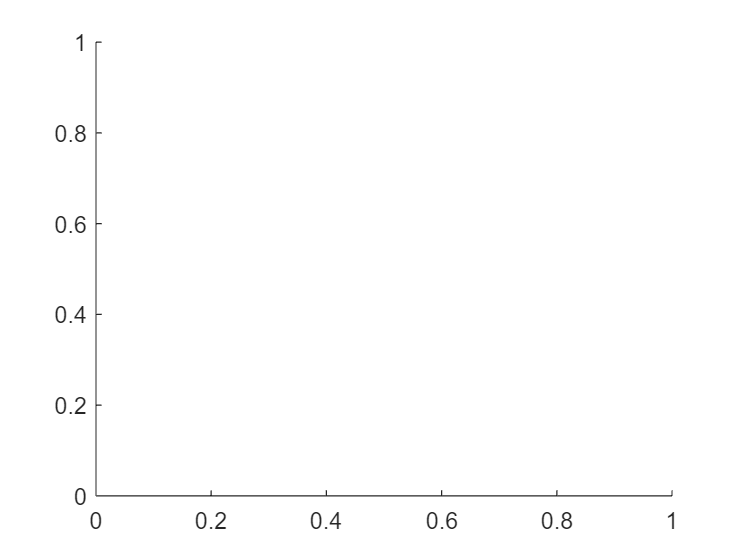

clear livescript

% Plot
hold off
hold on

% SEP
contour(speeds, alts, sep, [0:5:30, 500*(0.3048/60)], 'b')

Error using contour
The size of Y must match the size of Z or the number of rows of Z.

xlabel('Mach [-]')
ylabel('Altitude [m]')
title('Flight Envelope: A340-300')
legend('SEP [m/s]', 'Location','northwest')
xlim([0 1])

%%%% Envelope Boundaries
% clmax
altsample = 0:100:15000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
spds_clmax = sqrt(weight ./ (Sref * clmax * 0.5*rho_sample)) ./ a_sample;
plot(spds_clmax, altsample, 'k', 'LineWidth',1);

% c.Location = 'southoutside';
% c.Label.String = 'SEP [m/s]';

% qmax
altsample = 3000:100:15000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
vne_true = vne .* sqrt(rho0./rho_sample);
qmax = 0.5.*rho_sample.*vne_true.*vne_true;
spds_qmax = sqrt(2.*qmax ./ rho_sample) ./ a_sample;
plot(spds_qmax, altsample, 'k', 'LineWidth',1);

% Mne
plot([mne, mne], [0, 15000], 'k', 'LineWidth',1)

% airspace speed limit
% 250kts
altsample = 0:100:3000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
vmax = 250*1.852/3.6;
plot(vmax./a_sample, altsample, 'k', 'LineWidth',1)
% 3000m
qmax = 0.5*rho_sample(numel(rho_sample))*vne*vne*(rho0/rho);
plot([vmax/a_sample(numel(a_sample)), sqrt(2*qmax/rho_sample(numel(rho_sample))) / a_sample(numel(a_sample))], [3000, 3000], 'k', 'LineWidth',1)

### Task 4: Time-optimal climb path

for i=1:numel(alts)
    bestSEP = max(sep(i,:));
    if bestSEP < servicelimit_sep || isnan(bestSEP)
        bestSpd(i) = nan;
    else
        bestSpd(i) = speeds(find(sep(i,:) == bestSEP));
    end
end

plot(bestSpd, alts, 'r', 'LineWidth',1.25);

### Task 5: Total time to Service Ceiling (500ft/min)

servicelimit_sep = 500*(0.3048/60);

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_500fpm = time/60

### Task 6: Service Ceiling 100ft/min

servicelimit_sep = 100*(0.3048/60);

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_100fpm = time/60